# Are the Roundworms Alive or Dead?

 Uses Transfer learning to train a deep network that can classify images of roundworms as either alive or dead. (Alive worms are round; dead ones are straight.)

## Get the training images and classes

Create a datastore to the images.Specify the datastore where the Downloaded Folder is.

imds = imageDatastore('/home/akash/Downloads/deeplearning_course_files/Roundworms/WormImages/','FileExtensions',{'.jpg','.tif'});

Get the known classifications from a file and use these as the image labels.

groundtruth = readtable('WormData.csv');

groundtruth = 93×2 table
         File           Status  
    _______________    _________

    {'wormA01.tif'}    {'alive'}
    {'wormA02.tif'}    {'alive'}
    {'wormA03.tif'}    {'alive'}
    {'wormA04.tif'}    {'alive'}
    {'wormA05.tif'}    {'alive'}
    {'wormA06.tif'}    {'alive'}
    {'wormA07.tif'}    {'alive'}
    {'wormA08.tif'}    {'alive'}
    {'wormA09.tif'}    {'alive'}
    {'wormA10.tif'}    {'alive'}
    {'wormA11.tif'}    {'alive'}
    {'wormA12.tif'}    {'alive'}
    {'wormA13.tif'}    {'dead' }
    {'wormA14.tif'}    {'dead' }
    {'wormA15.tif'}    {'dead' }
    {'wormA16.tif'}    {'dead' }


imds.Labels = categorical(groundtruth.Status);%Attach labels to the image datastore, status describes whether the worm is dead or alive

View the first few images. The second argument to `imshow` scales the display based on the range of pixel values in the image.

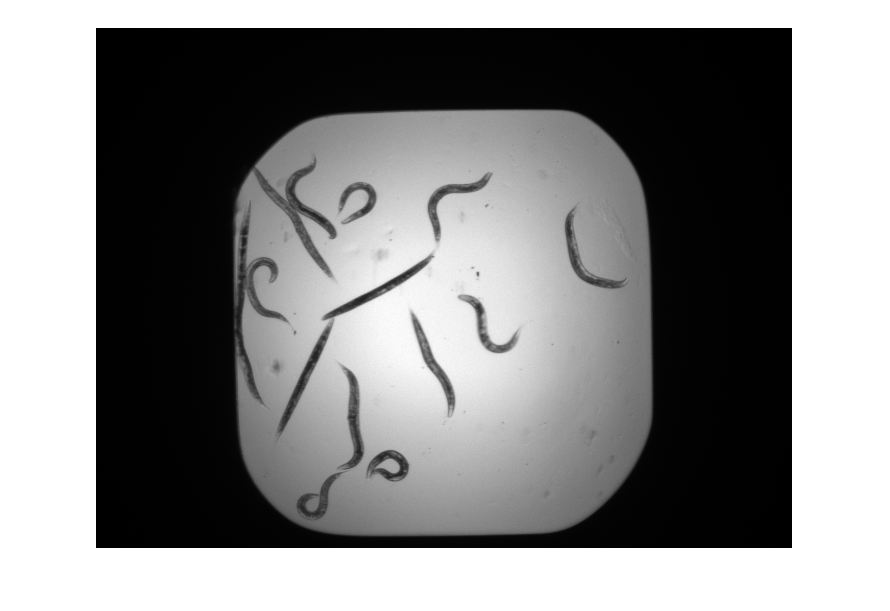

imshow(readimage(imds,1),[])% View the documentation of 'imshow' for more info

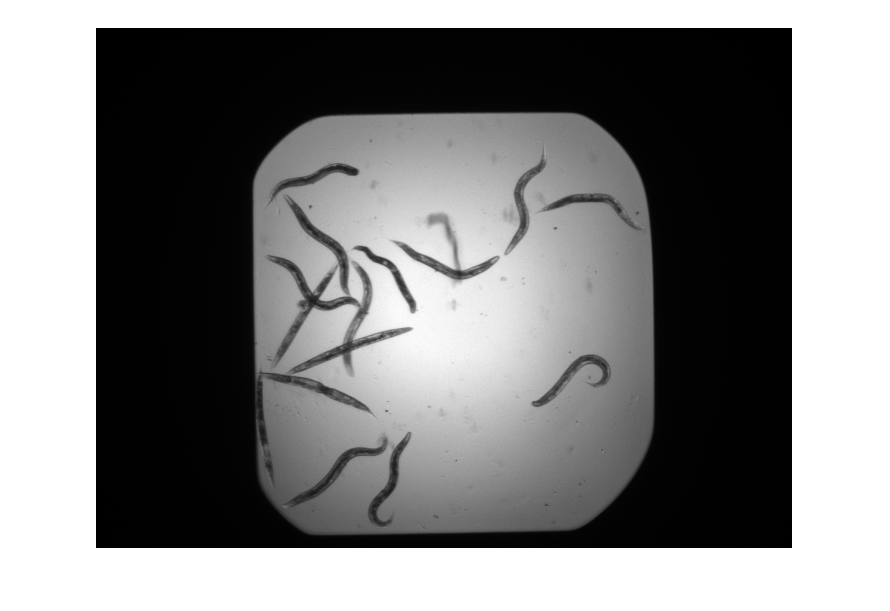

imshow(readimage(imds,2),[])

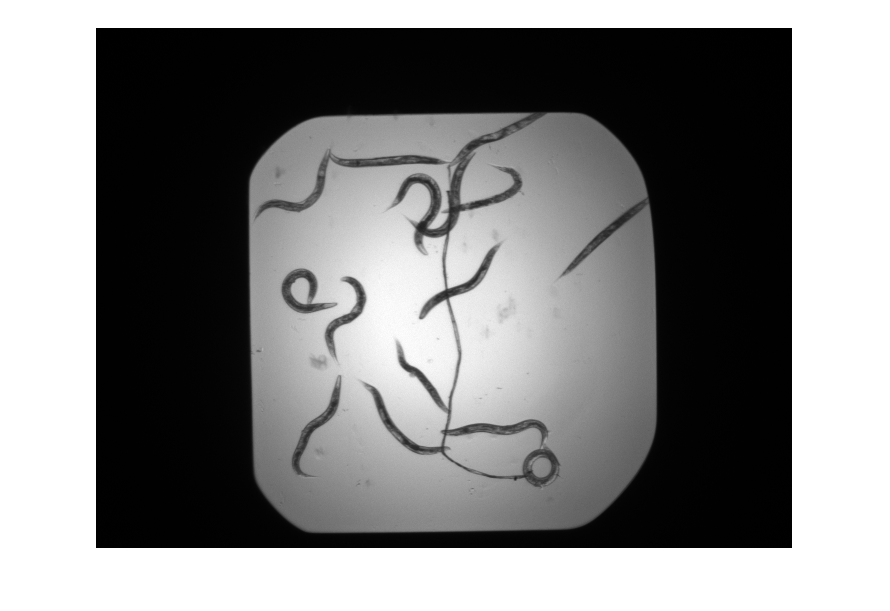

imshow(readimage(imds,3),[])

Divide data into training (60%) and testing (40%) sets

[trainImgs,testImgs] = splitEachLabel(imds,0.6,'randomized');

Create augmented image datastores to preprocess the images.

trainds = augmentedImageDatastore([227 227],trainImgs,'ColorPreprocessing','gray2rgb');
testds = augmentedImageDatastore([227 227],testImgs,'ColorPreprocessing','gray2rgb');

## Build a network

Start with a pretrained network

net = alexnet;

Take the CNN layers and add new classification layers at the end.

prebuiltLayers = net.Layers(1:end-3);
layers = [prebuiltLayers;fullyConnectedLayer(2);softmaxLayer;classificationLayer];

## Set some training options

topts = trainingOptions('adam','InitialLearnRate',0.0001);

## Train the network

wormsnet = trainNetwork(trainds,layers,topts)% One can change training parameters

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:22 |       44.64% |       2.4804 |      1.0000e-04 |
|      30 |          30 |       00:09:18 |      100.00% |   1.0005e-07 |      1.0000e-04 |
|========================================================================================|


wormsnet =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


## Evaluate network on test data

Make predictions

preds = classify(wormsnet,testds);

Compare with reality

truetest = testImgs.Labels;
nnz(preds == truetest)/numel(preds)

ans = 0.9730

View confusion matrix

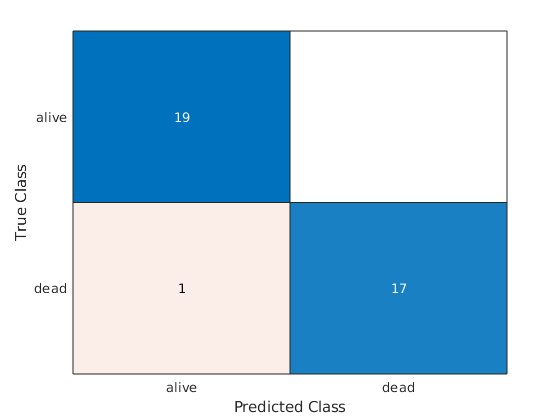

confusionchart(truetest,preds);